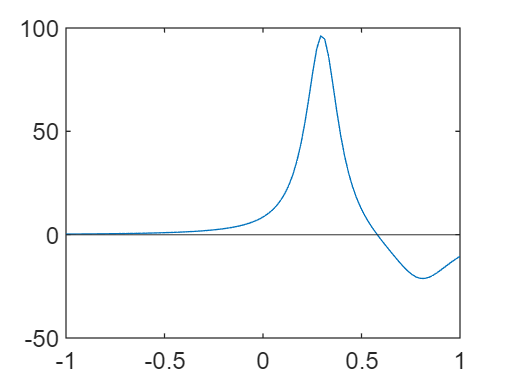

f = @(x) 1 ./ ((x-0.3).^2 + 0.01) - 1 ./ ((x-0.8).^2 + 0.04);
x = linspace(-1, 1);
plot(x, f(x))
hold on
yline(0)
hold off

x1 = 0.4; x2 = 0.8;
ermax = 1e-6;
[r, i] = ridder(f, x1, x2, ermax);
fprintf("La raíz es %.6f", r);

La raíz es 0.580000

fprintf("Se han requerido %d iteraciones", i);

Se han requerido 7 iteraciones

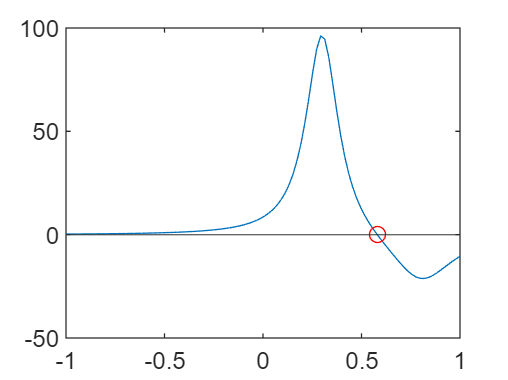

plot(x, f(x))
hold on
plot(r, f(r), 'ro')
yline(0)
hold off